# Euler-Bernoulli beam (dynamic, 1d)

## Constants

Nb = 4;
gauss_points_num = 8;
master = [0 1];
Npts = 100; % for plotting

% hermite cubic polynomials
coeffs = [1,0,-3,2; 
    0,1,-2,1;
    0,0,3,-2;
    0,0,-1,1];
L_const = 254;

s_const = 76.2;
sigma0_const = 1e6;
E_const = 20.7e9;
I_const = 249739;
d_const = 4.572*100;
c_const = 0.03;

A_const = s_const*sigma0_const;

B_const = log(10)/(c_const*d_const);
K_const = A_const/(E_const*I_const);

## Matrix assembly

L = L_const;
NEL = 20;
h = L/NEL;

% basis functions on the master element
N = basis_functions(coeffs);
d2_N = basis_derivatives(coeffs, 2);
d3_N = basis_derivatives(coeffs, 3);

% global nodes
xs = linspace(0,L,NEL+1);

% mesh sizes
hs = zeros(NEL,1);
for i=1:NEL
    hs(i) = xs(i+1) - xs(i);
end

% element nodes
es = zeros(NEL,2);
for i=1:NEL
    es(i,:) = [xs(i) xs(i+1)];
end

% local stiffness and mass matrices
Kl = zeros(Nb,Nb,NEL);
Ml = zeros(Nb,Nb,NEL);
for k=1:NEL
    for i=1:Nb
        for j=1:Nb
            Kl(i,j,k) = 1 / (hs(k))^3 * gauss(@(x) d2_N(i,x) * d2_N(j,x), master(1), master(2), gauss_points_num);
            Ml(i,j,k) =      hs(k)    * gauss(@(x)    N(i,x) *    N(j,x), master(1), master(2), gauss_points_num);
        end
    end
end

% Global matrices and force term
Kn = (NEL+1)*2;
K = zeros(Kn,Kn); M = zeros(Kn,Kn);
f = zeros(Kn);

for i=1:NEL
    K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Kl(1:Nb,1:Nb,i);
    M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Ml(1:Nb,1:Nb,i);
end

condest(K)

ans = 1.9925e+17

condest(M)

ans = 1.1725e+03

## Solver prep

v = @(x) 0;
w = @(x) 0;

% vs = project(@(x)1e-2*sin(x/L),@(x)1e-2*cos(x/L),xs); vs(1:2)=0;
% vs = [0
% 0
% 0.341146391985057
% 0.629072161598112
% 1.16739699525138
% 0.985585702184974
% 2.25050176746087
% 1.15621161317371
% 3.44265080483702
% 1.21489638593385
% 4.66348833825750
% 1.22279103572364];
vs = zeros(2*NEL+2,1);

% ws = 2e-3*sin(0:L/(2*(NEL+1)-1):L)';
ws = zeros(2*NEL+2,1);

T0 = 0; Tf = 1e6;
tau = 2e3; 
Ntsteps = round(Tf/tau+1);

lambda = tau^2;

A = M+lambda/4*K;
B = 2*M-lambda/2*K;

timesteps = ((0:500)*2000)';

% Use fixed point iteration for u
% Start with the initial guess
us = zeros(length(K),Ntsteps);

niter = 5;
us(:,1) = vs;

U2_guess = ones(length(K)-2,1);
us(3:end,2) = U2_guess;

% cholesky decomposition with reordering
[R1,~,p1] = chol(sparse(2*A(3:end,3:end)),'vector');
for i=1:niter
    force1 = K_const*construct_f(us(1:end,2),NEL,Nb,hs,master,gauss_points_num,N,B_const);
%     force1 = (((1:1:2*NEL+2)/(2*NEL+2)).^2)'/1e7;
    bvec1 = (B(3:end,3:end)*us(3:end,1) + 2*tau*A(3:end,3:end)*ws(3:end) + lambda*force1(3:end));
    us_temp1 = R1\(R1'\bvec1(p1)); us_temp1(p1) = us_temp1;
    us(3:end,2) = us_temp1;
end

% cholesky decomposition with reordering
[R,~,p] = chol(sparse(A(3:end,3:end)),'vector');
for j=3:Ntsteps
    us(3:end,j) = U2_guess; 
    for i=1:niter
        force = K_const*construct_f(us(1:end,j),NEL,Nb,hs,master,gauss_points_num,N,B_const);
%         force = (((1:1:2*NEL+2)/(2*NEL+2)).^2)'/1e7;
        bvec = B(3:end,3:end)*us(3:end,j-1) - A(3:end,3:end)*us(3:end,j-2) + lambda*force(3:end);
        us_temp = R\(R'\bvec(p)); us_temp(p) = us_temp;
        us(3:end,j) = us_temp;
    end
end

xxxs = linspace(0,L,Npts);
u_full = zeros(length(xxxs),Ntsteps);

for j=1:Ntsteps
    % local u coefficients
    u_locals = zeros(NEL, Nb);
    for i=1:NEL
        u_locals(i,1:end) = us(2*i-1: 2*i+Nb-2,j);
    end
    
    % producing piecewise polynomial approximation
    
    u_vals = zeros(length(xxxs),1);
    for i=1:length(xxxs)
        u_vals(i) = u_fun(u_locals, xxxs(i), NEL, Nb, N, es, xs);
    end
    u_full(1:end,j) = u_vals;
end

tip = (u_full(end,:))';

## Plotting

u_steady = [0
0.000999079441220923
0.00396889290802410
0.00886830311512016
0.0156561727772197
0.0242913646090334
0.0347327413252718
0.0469391656406455
0.0608695002698653
0.0764826079276415
0.0937373513286851
0.112592593187706
0.133007196219416
0.154940023138525
0.178349936659744
0.203195799497783
0.229436474367352
0.257030823983164
0.285937711059927
0.316115998312353
0.347524596609753
0.380126810405121
0.413892891033695
0.448793587195555
0.484799647590779
0.521881820919446
0.560010855881635
0.599157501177425
0.639292505506894
0.680386617570122
0.722410586067187
0.765335159698169
0.809131087163145
0.853769117162196
0.899219998395400
0.945454479562835
0.992443309364581
1.04015723650072
1.08856700967132
1.13764337757647
1.18735737904115
1.23768583777012
1.28860991402520
1.34011073818804
1.39216944064032
1.44476715176371
1.49788500193989
1.55150412155051
1.60560564097727
1.66017069060181
1.71518040080583
1.77061590197097
1.82645832447893
1.88268879871136
1.93928845504994
1.99623842387635
2.05351983557224
2.11111382051929
2.16900150909917
2.22716403169356
2.28558322846667
2.34424684880798
2.40314478149371
2.46226683115445
2.52160280242080
2.58114249992336
2.64087572829273
2.70079229215951
2.76088199615430
2.82113464490770
2.88154004305032
2.94208799521274
3.00276830602557
3.06357078011941
3.12448522212487
3.18550143667253
3.24660922839300
3.30779840191688
3.36905876187478
3.43038011289728
3.49175347309954
3.55317499099193
3.61464161271595
3.67615025599088
3.73769783853602
3.79928127807067
3.86089749231410
3.92254339898563
3.98421591580454
4.04591196049012
4.10762845076167
4.16936230433848
4.23111043893984
4.29286977228505
4.35463722209340
4.41640970608418
4.47818414197669
4.53995744749021
4.60172654034405
4.66348833825750];

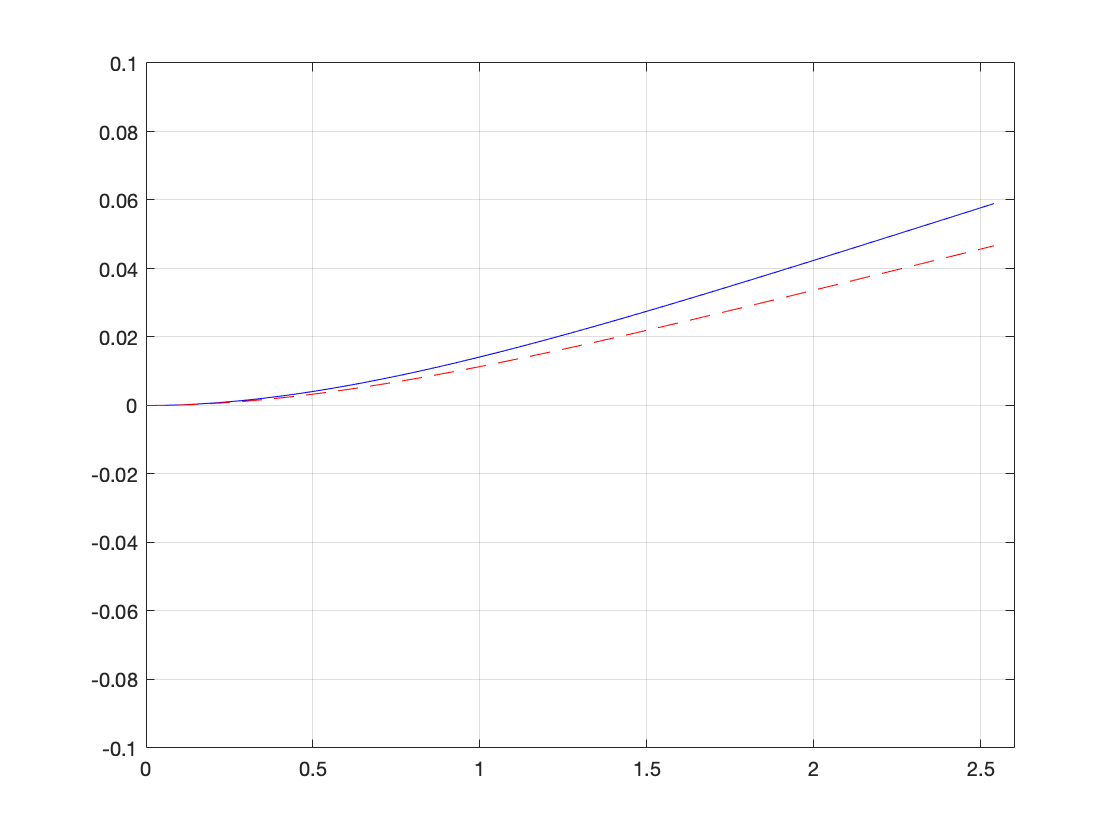

for j=1:Ntsteps
    plot(xxxs/100,u_full(1:end,j)/100,'b-',xxxs/100,u_steady/100,'r--')
    grid on
    xlim([0 2.6])
    ylim([-0.1 0.1])
    pause(.05)
end

## FEM tools

function res = exp(x,B_const)
    res = 1 + (-B_const*x) + (-B_const*x)^2/2 + (-B_const*x)^3/6 + (-B_const*x)^4/24;
end

function res = chi(e,x,xs) 
    res = false;
    if x > xs(e) && x <= xs(e+1)
        res = true;
    end
end

function res = xi(x,xe)
    res = (x - xe(1)) / (xe(2) - xe(1));
end

function res = get_u(u,xi,N)
    res = u(1)*N(1,xi) + u(2)*N(2,xi) + u(3)*N(3,xi) + u(4)*N(4,xi);
end

function f_global = construct_f(us,NEL,Nb,hs,master,gauss_points_num,N,B_const)
    u_local = zeros(NEL, Nb);
    for i=1:NEL
        u_local(i,:) = us(2*i-1:2*i+Nb-2);
    end
        
    f_local = zeros(NEL,Nb);
    for i=1:NEL
        for j=1:4
            f_local(i,j) = hs(i)*gauss(@(x) N(j,x) * exp(get_u(u_local(i,:),x,N),B_const), master(1), master(2), gauss_points_num);
        end
    end
    
    f_global = zeros(length(us),1);
    for i=1:NEL
        f_global(2*i-1:2*i+Nb-2) = f_global(2*i-1:2*i+Nb-2) + f_local(i,1:Nb)';
    end
end

% assemble u(x) from u_i coefficients
function res = u_fun(u_locals, x, NEL, Nb, N, es, xs)
    res = 0;
    for i=1:NEL
        sm = 0;
        for j=1:Nb
            sm = sm + u_locals(i,j) * N(j,xi(x,es(i,:)));
        end
        sm = sm * chi(i,x,xs);
        res = res + sm;
    end
end

function q = get_q(u_locals, es, d2_N, d3_N)
    q = zeros(2);
    e = 0;
    for j=1:Nb
        q(1) = q(1) + u_locals(e,j) * d2_N(j,xi(1,es(e)));
        q(2) = q(2) + u_locals(e,j) * d3_N(j,xi(1,es(e)));
    end
    q = q/100;
end

## Polynomial tools

function basis = basis_functions(coefficient_matrix)
    mat_size = length(coefficient_matrix);
    basis = @(index, x) coefficient_matrix(index,1:mat_size)*(x.^(0:mat_size-1))';
end

function der_mat = derivative_matrix(basis_order, derivative_order)
    der_mat = zeros(basis_order, basis_order);
    for i=derivative_order+1:basis_order
        prod = 1;
        for j=1:derivative_order
            prod = prod*(i-j);
        end
        der_mat(i-derivative_order,i) = prod;
    end
    der_mat = sparse(der_mat');
end

function res = basis_derivatives(coefficient_matrix, order)
    der_mat = derivative_matrix(length(coefficient_matrix), order);
    res = basis_functions(coefficient_matrix*der_mat);
end

function res = gauss(fun, a, b, order)
    [x,w] = lgwt(order,a,b);
    f = arrayfun(fun,x);
    res = sum(f.*w);
end

## Projection onto FEM space

function proj = project(fun, dfun, xs)
    proj = zeros(2*length(xs),1);
    for i=1:length(xs)
        proj(2*i-1) = fun(xs(i));
        proj(2*i) = dfun(xs(i));
    end
end